# ECM307-G01T02L03D - Atividade T1 

## Atividade T1 analogia entre vetores e sinais

## Luis Guilherme de Souza Munhoz RA: 20.01937-8 Lab: 3

## Boas Práticas

clc;                % limpa a tela
clear all;          % limpar as variáveis
close all;          % fecha as figuras abertas


## Item 1

#### 
$$g\left(t\right)=e^{-t}$$


## Item 2

#### 
$$g_n \left(t\right)=e^{-\textrm{jn}\omega_0 t}$$


## Definindo variáveis e funções a serem estudadas

syms t n T0
%% Declaração de funções
gt = @(t) exp(-t);                                                              % função base
gn = @(n,t,w0) exp(-j*n*w0*t);                                                  % função a ser decomposta
gt2 = @(t) exp(-10*t);                                                          %função para pergunta 1
gt3 = @(t) exp(-(t-1));  

## Item 3

#### 
$$c_{n\;} =\frac{\int_{T_0 } g\left(t\right)g_n \left(t\right)\textrm{dt}}{\int_{T_0 } g_n {\left(t\right)}^2 }$$


## Análise simbólica e numérica

%% Questão 1

%% Inicializando vaiáveis
syms t                                                                          % definindo tempo como simbólico        
T0 = 1;                                                                         % Período
N  = 20;                                                                         % número de harmônicas
w0 = 2*pi/T0                                                                    % frequência ângular

w0 = 6.2832

%% Determinação dos coeficientes c0, c1 e c_menos1
c0 = projecao(gt(t),gn(0,t,w0),T0)                                              % coeficiente c0

c0 = 0.6321

c1 = projecao(gt(t),gn(1,t,w0),T0)                                              % coeficiente c1

c1 = 0.0156 - 0.0981i

c_menos1 = projecao(gt(t),gn(-1,t,w0),T0)                                       % coeficiente c_menos1

c_menos1 = 0.0156 + 0.0981i



% determinação dos coeficientes para exp(-10t)
c02 = projecao(gt2(t),gn(0,t,w0),T0)                                            % coeficiente c0

c02 = 0.1000

c03 = projecao(gt3(t),gn(0,t,w0),T0)                                            % coeficiente c0

c03 = 1.7183

c12 = projecao(gt2(t),gn(1,t,w0),T0)                                            % coeficiente c1

c12 = 0.0717 - 0.0450i

c_menos12 = projecao(gt2(t),gn(-1,t,w0),T0)                                     % coeficiente c_menos1

c_menos12 = 0.0717 + 0.0450i

% cálculo das projeções p02(t) e p1_2(t) e do resíduo r1_2(t)
t = linspace(0,T0,1000);                                                        % vetor tempo  
p03 = c03*gn(0,t,w0);                                                           % projeção para n = 0 
p02 = c02*gn(0,t,w0);                                                           % projeção para n = 0
p1_2 = p02 + c12*gn(-1,t,w0) + c_menos12*gn(1,t,w0);                            % projeção para n = 1
r1_2 = gt2(t) - p1_2;                                                           % resíduo para n = 1

% cálculo das projeções p0(t) e p1(t) e do resíduo r1(t)
t = linspace(0,T0,1000);                                                        % vetor tempo   
p0 = c0*gn(0,t,w0);                                                             % projeção para n = 0
p1 = p0 + c1*gn(-1,t,w0) + c_menos1*gn(1,t,w0);                                 % projeção para n = 1
r1 = gt(t) - p1;                                                                % resíduo para n = 1


## Comparando p1(t) com g(t) e r1(t) e plotando o novo sinal e comparando

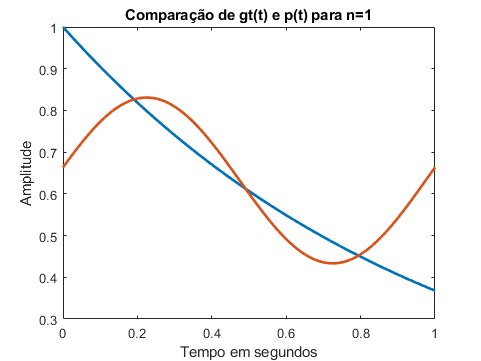

Current plot held


%% plotando curvas para comparação
figure(1)
plot(t,gt(t),'LineWidth',2), title('Comparação de gt(t) e p(t) para n=1');
hold; plot(t,p1,'LineWidth',2), xlabel("Tempo em segundos"),ylabel("Amplitude")

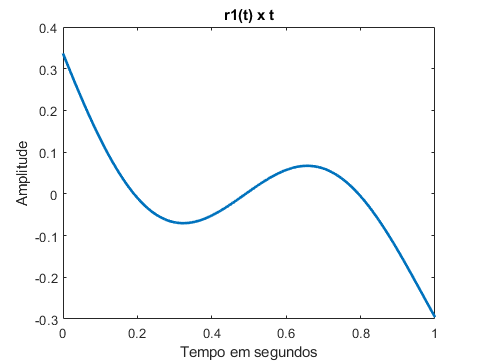

figure(2)
plot(t,r1,'LineWidth',2), title('r1(t) x t'), xlabel("Tempo em segundos"),ylabel("Amplitude")

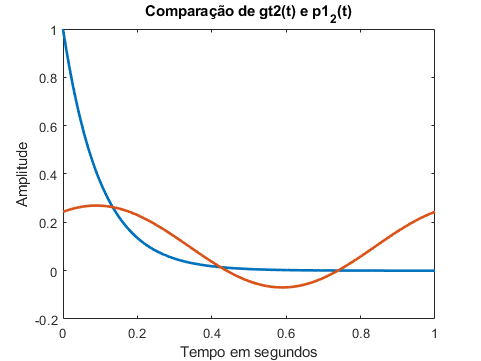

Current plot held


figure(3)
plot(t,gt2(t),'LineWidth',2), title('Comparação de gt2(t) e p1_2(t)');
hold; plot(t,p1_2,'LineWidth',2), xlabel("Tempo em segundos"),ylabel("Amplitude")

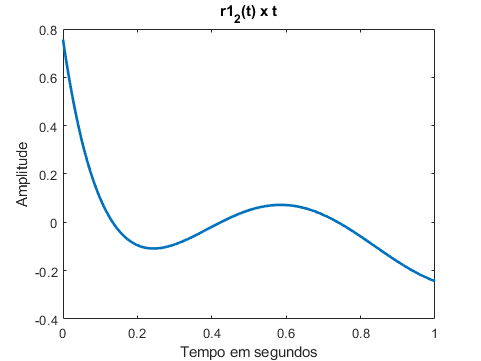

figure(4)
plot(t,r1_2,'LineWidth',2), title('r1_2(t) x t'), xlabel("Tempo em segundos"),ylabel("Amplitude")

## Item 4

%% redefinição das variáveis como simbólicas
syms t p12
%% Determinação dos coeficientes c2 e c-2
c2 = projecao(gt(t),gn(2,t,w0),T0)                                              % coeficiente c2

c2 = 0.0040 - 0.0500i

c_menos2 = projecao(gt(t),gn(-2,t,w0),T0)                                       % coeficiente c_menos2

c_menos2 = 0.0040 + 0.0500i

%% criação da função resíduo para cálculo de c2 e c-2 a partir do resíduo r1(t)
residuo = @(gt, p) gt - p12;                                                    % função resíduo para cálculo de c2 e c_menos2 de outra forma

%%cálculo de c2 e c-2 a partir do resíduo r1(t)
c22 = projecao(residuo(gt(t),p12),gn(2,t,w0),T0)                                % coeficiente c2 a partir do resíduo r1(t)

c22 = 0.0040 - 0.0500i

c_menos22 = projecao(residuo(gt(t),p12),gn(-2,t,w0),T0)                         % coeficiente c_menos2 a partir do resíduo r1(t)

c_menos22 = 0.0040 + 0.0500i

t = linspace(0,T0,1000);                                                        % vetor tempo
p12 = c1*gn(-2,t,w0) + c_menos1*gn(2,t,w0);                                     % recalculando a projeção p1(t) para cálculo de r1(t)

%% cálculo da diferença entre os diferentes c2 e c-2 calculados
difc2 = abs(c2-c22)                                                             % diferença entre c2 e c2 a partir do resíduo

difc2 = 0

difcmenos2 = abs(c_menos2-c_menos22)                                            % diferença entre c_menos2 e c_menos2 a partir do resíduo

difcmenos2 = 0

%% mostrando a resposta no terminal
disp('Pode-se ver que a diferença entre os cálculos de c2 e c_menos 2 é 0 pois o sinal gn(t), para n = 2, é ortogonal a gn(t) para n = 1, assim sendo indiferente usar a exponencial gt(t) ou o resíduo r1(t) para o cálculo de c2 e c_menos2.');

Pode-se ver que a diferença entre os cálculos de c2 e c_menos 2 é 0 pois o sinal gn(t), para n = 2, é ortogonal a gn(t) para n = 1, assim sendo indiferente usar a exponencial gt(t) ou o resíduo r1(t) para o cálculo de c2 e c_menos2.


% determinação dos coeficientes para exp(-10t)
syms t
c2_2 = projecao(gt2(t),gn(2,t,w0),T0)                                           % coeficiente c2

c2_2 = 0.0388 - 0.0487i

c2_menos2 = projecao(gt2(t),gn(-2,t,w0),T0)                                     % coeficiente c_menos2

c2_menos2 = 0.0388 + 0.0487i

% cálculo das projeções p02(t) e p1_2(t) e do resíduo r1_2(t)
t = linspace(0,T0,1000);                                                        % vetor tempo   
p2_2 = p1_2 + c2_2*gn(-2,t,w0) + c2_menos2*gn(2,t,w0);                          % projeção para n = 1
r2_2 = gt2(t) - p2_2;                                                           % resíduo para n = 1

%% cálculo numérico da projeção p2 e resíduo r2
p2 = p1 + c2*gn(-2,t,w0) + c_menos2*gn(2,t,w0);                                 % cálculo da projeção p2(t)
r2 = gt(t) - p2;                                                                % cálculo do resíduo r2(t)

## comparando p2(t) e g(t) com r2(t) e comparando o novo sinal

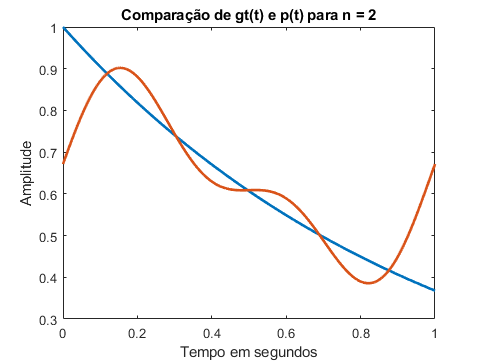

Current plot held


%% plotando as curvas
figure(5)
plot(t,gt(t),'LineWidth',2), title('Comparação de gt(t) e p(t) para n = 2');
hold; plot(t,p2,'LineWidth',2), xlabel("Tempo em segundos"),ylabel("Amplitude")

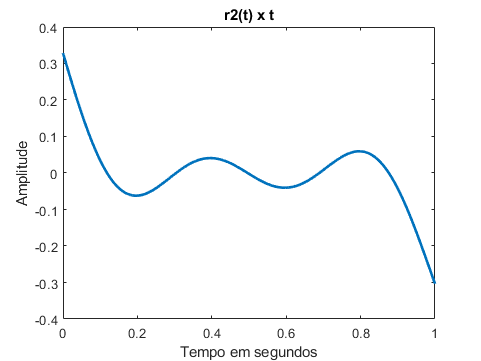

figure(6)
plot(t,r2,'LineWidth',2),title('r2(t) x t'),xlabel("Tempo em segundos"),ylabel("Amplitude")

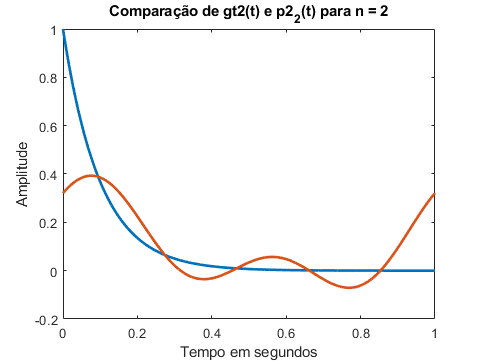

Current plot held


%% plotando as curvas
figure(7)
plot(t,gt2(t),'LineWidth',2), title('Comparação de gt2(t) e p2_2(t) para n = 2');
hold; plot(t,p2_2,'LineWidth',2), xlabel("Tempo em segundos"),ylabel("Amplitude")

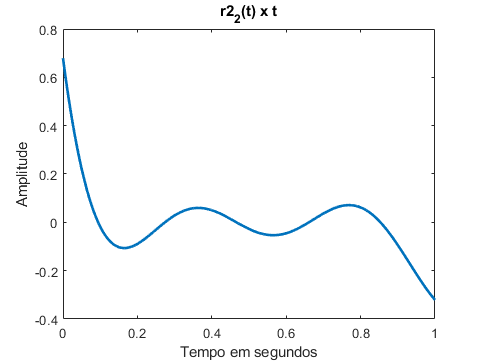

figure(8)
plot(t,r2_2,'LineWidth',2),title('r2_2(t) x t'),xlabel("Tempo em segundos"),ylabel("Amplitude")

## Item 5

## cálculo iterativo

pk0 = p0;                                                                       % inicializando variável pk0 e atribuindo p0 a ela
pk02 = p02

pk02 =     0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000


pk03 = p03

pk03 =     1.7183    1.7183    1.7183    1.7183    1.7183    1.7183    1.7183    1.7183    1.7183    1.7183    1.7183    1.7183    1.7183    1.7183    1.7183    1.7183    1.7183    1.7183    1.7183    1.7183    1.7183    1.7183    1.7183    1.7183    1.7183    1.7183    1.7183    1.7183    1.7183    1.7183    1.7183    1.7183    1.7183    1.7183    1.7183    1.7183    1.7183    1.7183    1.7183    1.7183    1.7183    1.7183    1.7183    1.7183    1.7183    1.7183    1.7183    1.7183    1.7183    1.7183


for k=1:N                                                                       % intervalo do for de 1 ao número de harmônicas definido anteriormente
    syms t                                                                      % definindo t como simbólico para cálculo de ck e c_menosk
    ck = projecao(gt(t),gn(k,t,w0),T0);                                         % cálculo do coeficiente ck
    cg1(k) = ck;                                 
    c_menosk = projecao(gt(t),gn(-k,t,w0),T0);                                  % cálculo do coeficiente c_menosk
    ck2 = projecao(gt2(t),gn(k,t,w0),T0);                                       % cálculo do coeficiente ck2
    cg2(k) = ck2;                                       
    c_menosk2 = projecao(gt2(t),gn(-k,t,w0),T0);                                % cálculo do coeficiente c_menosk2
    ck3 = int(gt3(t)*gn(k,t,w0),t,1,2)/int(abs(gn(k,t,w0))^2,t,1,2);            % cálculo do coeficiente ck2
    cg3(k) = ck3;                                       
    c_menosk3 = int(gt3(t)*gn(k,t,w0),t,1,2)/int(abs(gn(k,t,w0))^2,t,1,2);      % cálculo do coeficiente c_menosk2
    t= linspace(0,T0,1000);                                                     % vetor tempo numérico para cálculo das projeções
    pk = pk0 + ck*gn(-k,t,w0) + c_menosk*gn(k,t,w0);                            % somatória das projeções pk
    rk = gt(t) - (pk);                                                          % resíduo rk(t)
    pk2 = pk02 + ck2*gn(-k,t,w0) + c_menosk2*gn(k,t,w0);                        % somatória das projeções pk
    rk2 = gt2(t) - (pk2);                                                       % resíduo rk(t)
    pk0 = pk;                                                                   % atribuindo pk a pk0 para continuar a somatória na próxima iteração
    pk02 = pk2;
end                                                                             % fim do loop

## exibindo o gráfico final e comparando g(t) pn(t) e rn(t)

figure(9)
plot(t,gt(t),'LineWidth',2), title('Comparação de gt(t) e somatória das projeções p(t)');
hold;

Current plot held


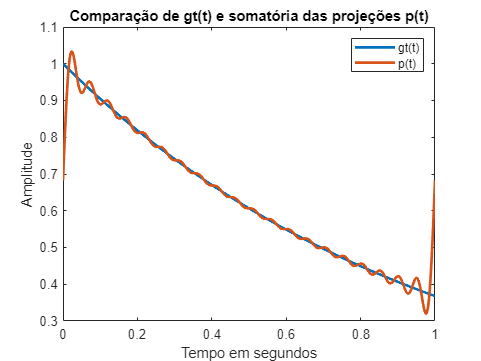

plot(t,pk,'LineWidth',2),xlabel("Tempo em segundos"),ylabel("Amplitude")
legend('gt(t)','p(t)');

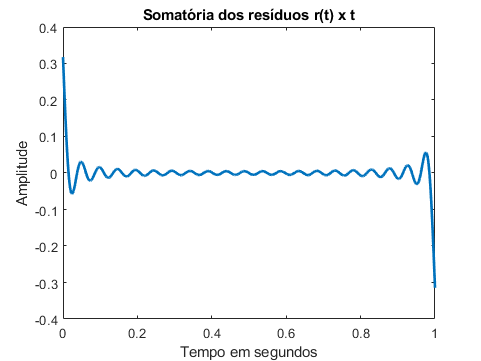

figure(10)
plot(t,rk,'LineWidth',2), title('Somatória dos resíduos r(t) x t');xlabel("Tempo em segundos"),ylabel("Amplitude")

figure(11)
plot(t,gt2(t),'LineWidth',2), title('Comparação de gt2(t) e somatória das projeções p(t)');
hold;

Current plot held


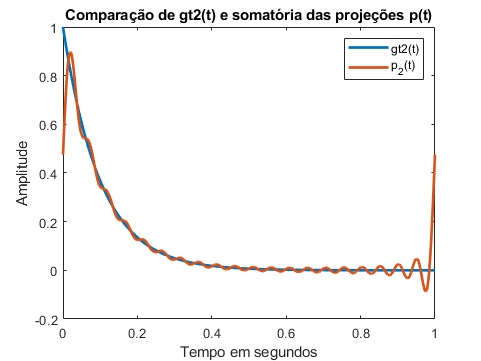

plot(t,pk2,'LineWidth',2),xlabel("Tempo em segundos"),ylabel("Amplitude")
legend('gt2(t)','p_2(t)');

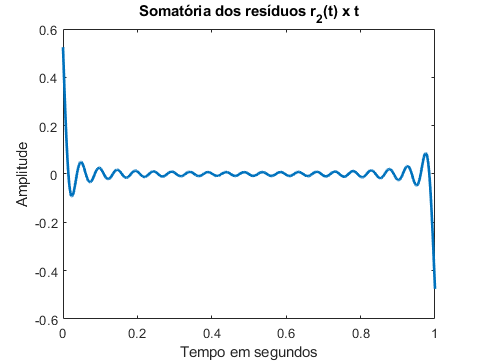

figure(12)
plot(t,rk2,'LineWidth',2), title('Somatória dos resíduos r_2(t) x t');xlabel("Tempo em segundos"),ylabel("Amplitude")

figure(13)
t= linspace(0,T0,20)

t =          0    0.0526    0.1053    0.1579    0.2105    0.2632    0.3158    0.3684    0.4211    0.4737    0.5263    0.5789    0.6316    0.6842    0.7368    0.7895    0.8421    0.8947    0.9474    1.0000


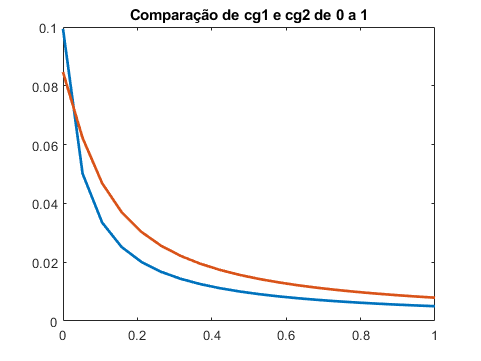

Current plot held


plot(t,abs(cg1),'LineWidth',2), title('Comparação de cg1 e cg2 de 0 a 1');
hold; plot(t,abs(cg2),'LineWidth',2)

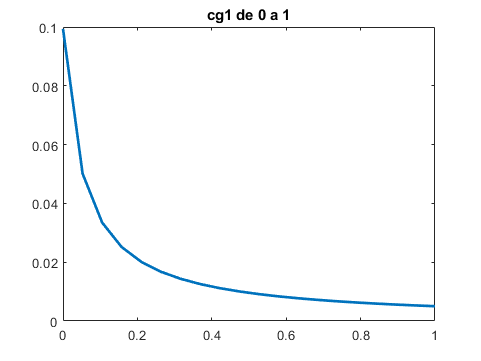

figure(14)
plot(t,abs(cg1),'LineWidth',2), title('cg1 de 0 a 1');

t= linspace(1,2,20)

t =     1.0000    1.0526    1.1053    1.1579    1.2105    1.2632    1.3158    1.3684    1.4211    1.4737    1.5263    1.5789    1.6316    1.6842    1.7368    1.7895    1.8421    1.8947    1.9474    2.0000


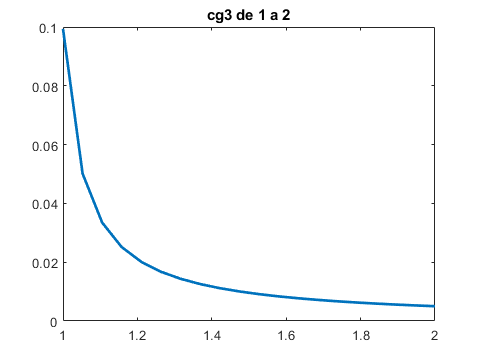

figure(15)
plot(t,abs(cg3),'LineWidth',2), title('cg3 de 1 a 2');

## questao 2 cálculo potência

syms t
pg1 = 1/T0*int(gt(t)^2,t,0,T0);
pg2 = 1/T0*int(gt2(t)^2,t,0,T0);

pg1 = eval(pg1)

pg1 = 0.4323

pg2 = eval(pg2)

pg2 = 0.0500


%% pode-se ver que a potência de pg1 é maior devido a frequência cg1 ser menor que cg2 pela maior parte do intervalo


## questao 3

%% a partir do gráfico plotado na figura percebe-se que teria somente a parte de cima da interseção entre as 2 curvas ao limitar o intervalo

## questao 4

pg3 = 1/T0*int(gt3(t)^2,t,1,2);
pg3 = eval(pg3)

pg3 = 0.4323

%% percebe-se que a potência pg1 é igual a potência pg3 e a curva cg1 é igual a curva cg3, isso acontece pois as duas curvas variam de e^0 a e^1 ao substituir o intervalo do tempo em cada curva

## função projeção

function [c] = projecao(gt,gn,T0)

% calcula c

syms t

%%% Projeção simbólica

cn = int(gt*gn,t,0,T0)/int(abs(gn)^2,t,0,T0);

%%% Projeção Numérica

c = eval(cn);

end